Testing whether the proportion of dist bin 1 similarity compared to bin2 / bin1 to bin 3 , is related to the y coordinate of the hippocampal voxels zTemplate is calculated from 

[dt03, mmY] = getDataTable03();


formula = 'zCorr_m1 ~ hemisphere*coLocation*mcPnonc + (1| subjectId)';
mdl3_star = fitlme(dt03,formula)

mdl3_star = Linear mixed-effects model fit by ML

Model information:
    Number of observations             124
    Fixed effects coefficients           8
    Random effects coefficients         31
    Covariance parameters                2

Formula:
    zCorr_m1 ~ 1 + hemisphere*coLocation + hemisphere*mcPnonc + coLocation*mcPnonc + hemisphere:coLocation:mcPnonc + (1 | subjectId)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    126.34    154.54    -53.169          106.34  

Fixed effects coefficients (95% CIs):
    Name                                     Estimate     SE          tStat      DF     pValue       Lower        Upper     
    {'(Intercept)'                  }         0.039658    0.033363     1.1887    116        0.237    -0.026422       0.10574
    {'hemisphere'                   }        -0.043097    0.033363    -1.2917    116      0.19902     -0.10918      0.0

zErr = zscore(residuals(mdl3_star));
s = abs(zErr) > 2.5;
mdl3 = fitlme(dt03,formula,'Exclude',s)

mdl3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             123
    Fixed effects coefficients           8
    Random effects coefficients         31
    Covariance parameters                2

Formula:
    zCorr_m1 ~ 1 + hemisphere*coLocation + hemisphere*mcPnonc + coLocation*mcPnonc + hemisphere:coLocation:mcPnonc + (1 | subjectId)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -312.18    -284.06    166.09           -332.18 

Fixed effects coefficients (95% CIs):
    Name                                     Estimate       SE           tStat       DF     pValue      Lower         Upper    
    {'(Intercept)'                  }           0.003293     0.005659      0.5819    115     0.56178    -0.0079164     0.014502
    {'hemisphere'                   }         -0.0067314     0.005659     -1.1895    115     0.23669     -0.017941

% mdl3 = fitlme(dt03,formula);
pVals = dataset2table(mdl3.Coefficients(:,'pValue'));
coefficient = dataset2table(mdl3.Coefficients(:,'Name'));
[alphas,h] = holmBonf(0.05,pVals{:,1});
alphas = table(alphas);
mC = [coefficient,pVals,alphas];
mC.Properties.VariableNames = {'coefficient','pVal','corrected_Alpha_Level'};
disp(mC);

               coefficient                 pVal      corrected_Alpha_Level
    _________________________________    ________    _____________________

    {'(Intercept)'                  }     0.56178              0.025      
    {'hemisphere'                   }     0.23669          0.0083333      
    {'coLocation'                   }     0.46869             0.0125      
    {'mcPnonc'                      }     0.48409           0.016667      
    {'hemisphere:coLocation'        }      0.4334               0.01      
    {'hemisphere:mcPnonc'           }     0.12202          0.0071429      
    {'coLocation:mcPnonc'           }     0.75713               0.05      
    {'hemisphere:coLocation:mcPnonc'}    0.031347            0.00625      



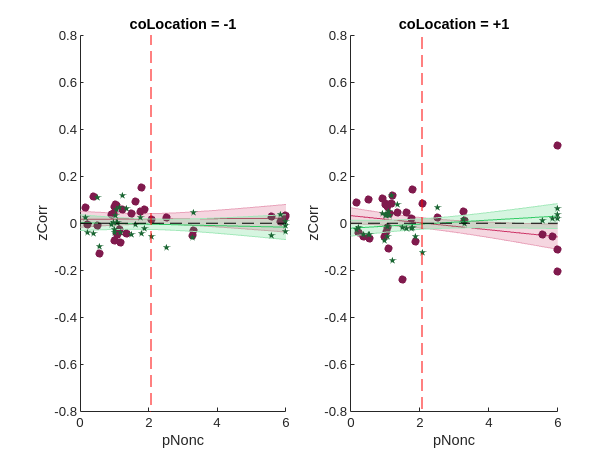


domain.mu = mean(dt03.pNonc);
domain.p = linspace(0,6,144)';
domain.cp = domain.p - domain.mu;

figure;

subplot(121);
hold on;
%%% coloc = -1, left
colocation = -1;
hemisphere = -1;
s = (dt03.coLocation == colocation) & ...
    (dt03.hemisphere == hemisphere);
[X,y,low,upp] = getXEUL(mdl3,...
    1,hemisphere,colocation,domain.cp);
shadedErrorBar(domain.p',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.8,0.2,0.4]});
scatter(dt03.pNonc(s),dt03.zCorr_m1(s),30,...
    [0.5,0.1,0.3],'filled');

%%% coloc = -1, right 
colocation = -1;
hemisphere = +1;
s = (dt03.coLocation == colocation) & ...
    (dt03.hemisphere == hemisphere);
[X,y,low,upp] = getXEUL(mdl3,...
    1,hemisphere,colocation,domain.cp);
shadedErrorBar(domain.p',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.2,0.8,0.4]});
scatter(dt03.pNonc(s),dt03.zCorr_m1(s),30,...
    [0.1,0.4,0.2],'filled','pentagram');

%% Appearence
ylabel('zCorr');
xlabel('pNonc');
ylim([-.8,.8]);
xlim([0,6]);
line([0,6],[0,0],'Color','k','LineStyle','--');
line([domain.mu,domain.mu],[-1.5, 1.5],'Color','r','LineStyle','--');
title('coLocation = -1');
hold off;

subplot(122);
hold on;
%%% coloc = +1, left
colocation = +1;
hemisphere = -1;
s = (dt03.coLocation == colocation) & ...
    (dt03.hemisphere == hemisphere);
[~,y,low,upp] = getXEUL(mdl3,...
    1,hemisphere,colocation,domain.cp);
shadedErrorBar(domain.p',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.8,0.2,0.4]});
h1 = scatter(dt03.pNonc(s),dt03.zCorr_m2(s),30,...%change back!
    [0.5,0.1,0.3],'filled');

%%% coloc = +1, right 
colocation = +1;
hemisphere = +1;
s = (dt03.coLocation == colocation) & ...
    (dt03.hemisphere == hemisphere);
[~,y,low,upp] = getXEUL(mdl3,...
    1,hemisphere,colocation,domain.cp);
shadedErrorBar(domain.p',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.2,0.8,0.4]});
h2 = scatter(dt03.pNonc(s),dt03.zCorr_m1(s),30,... %change back!
    [0.1,0.4,0.2],'filled','pentagram');

%% Appearence
ylabel('zCorr');
xlabel('pNonc');
ylim([-.8,.8]);
xlim([0,6]);
line([0,6],[0,0],'Color','k','LineStyle','--');
h3 = line([domain.mu,domain.mu],[-1.5, 1.5],'Color','r','LineStyle','--');
title('coLocation = +1');
hold off;


% lgd = legend([h1,h2,h3],{'left','right','mu pNonc'});
% %lgd.Layout.Tile = 11;
% lgd.Location = 'northeastoutside';
% lgd.ItemTokenSize = [8 6];
